Este es el codigo generado para la 6ta clase de Matemáticas Aplicadas.

Resolveremos la siguiente ecuación diferencial con valores iniciales


$$\frac{d^2y}{dt^2} + 7\frac{dy}{dt}+25y = e^{-4t}$$


Con las condiciones


$$y(1) =2, \;\;\; y\prime(1)=0$$


Introduciones las variables simbólicas, definimos la ecuacion y establecemos las condiciones:

syms y(t) t;
ec = diff(y,t,2)+7*diff(y,t,1)+25*y==exp(-4*t);
Dy=diff(y,t,1);
cond=[y(1)==2 Dy(1)==0];

Resolvemos la ecuacion, a continuacion se muestra la solucion general y la particular

ygeneral=dsolve(ec)

$$ygeneral = \begin{array}{l} C_{1}\,\sigma_{3}\,\sigma_{2}-C_{2}\,\sigma_{3}\,\sigma_{1}+\frac{2\,\sqrt{51}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sigma_{3}\,\sigma_{2}\,\left(\frac{\sigma_{1}}{2}+\frac{\sqrt{51}\,\sigma_{2}}{2}\right)}{663}-\frac{2\,\sqrt{51}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sigma_{3}\,\sigma_{1}\,\left(\frac{\sigma_{2}}{2}-\frac{\sqrt{51}\,\sigma_{1}}{2}\right)}{663}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\sqrt{51}\,t}{2}\right)\\ \sigma_{2}=\cos\left(\frac{\sqrt{51}\,t}{2}\right)\\ \sigma_{3}={\mathrm{e}}^{-\frac{7\,t}{2}} \end{array}$$

yparticular=dsolve(ec,cond)

$$yparticular = \begin{array}{l} \frac{2\,\sqrt{51}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sigma_{1}\,\cos\left(\sigma_{2}\right)\,\left(\frac{\sin\left(\sigma_{2}\right)}{2}+\frac{\sqrt{51}\,\cos\left(\sigma_{2}\right)}{2}\right)}{663}-\frac{2\,\sqrt{51}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sigma_{1}\,\sin\left(\sigma_{2}\right)\,\left(\frac{\cos\left(\sigma_{2}\right)}{2}-\frac{\sqrt{51}\,\sin\left(\sigma_{2}\right)}{2}\right)}{663}+\frac{\sigma_{1}\,{\mathrm{e}}^{-\frac{1}{2}}\,\sin\left(\sigma_{2}\right)\,\left(\sigma_{4}\,{\sigma_{5}}^{2}-\sqrt{51}\,{\sigma_{5}}^{3}+{\sigma_{4}}^{3}+182\,\sigma_{4}\,{\mathrm{e}}^{4}+26\,\sqrt{51}\,\sigma_{5}\,{\mathrm{e}}^{4}-\sqrt{51}\,{\sigma_{4}}^{2}\,\sigma_{5}\right)}{13\,\sigma_{3}}-\frac{\sigma_{1}\,{\mathrm{e}}^{-\frac{1}{2}}\,\cos\left(\sigma_{2}\right)\,\left(51\,\sigma_{4}\,{\sigma_{5}}^{3}+51\,{\sigma_{4}}^{3}\,\sigma_{5}+51\,\sqrt{51}\,{\sigma_{4}}^{4}+9282\,\sigma_{4}\,\sigma_{5}\,{\mathrm{e}}^{4}-1326\,\sqrt{51}\,{\sigma_{4}}^{2}\,{\mathrm{e}}^{4}+51\,\sqrt{51}\,{\sigma_{4}}^{2}\,{\sigma_{5}}^{2}\right)}{663\,\sigma_{4}\,\sigma_{3}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{7\,t}{2}}\\ \sigma_{2}=\frac{\sqrt{51}\,t}{2}\\ \sigma_{3}=\sqrt{51}\,{\sigma_{4}}^{2}+\sqrt{51}\,{\sigma_{5}}^{2}\\ \sigma_{4}=\cos\left(\frac{\sqrt{51}}{2}\right)\\ \sigma_{5}=\sin\left(\frac{\sqrt{51}}{2}\right) \end{array}$$

Procedemos a graficar lo obtenido

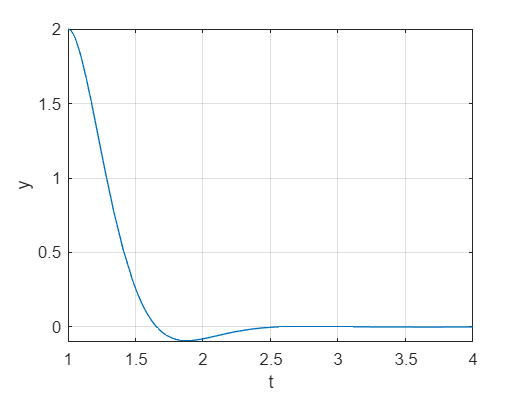

fplot(yparticular,[1,4]), grid, xlabel('t'),ylabel('y')

Ahora realizaremos lo anterior pero usando un método diferente

Aqui vamos a definir las variables de estado como


$$y=y(1), \;\;\; y\prime=y(2), \;\;\; y\prime\prime=y(3)$$


f1 = @(t,y) [y(2); exp(-4*t)-25*y(1)-7*y(2)]

f1 = function_handle with value:
    @(t,y)[y(2);exp(-4*t)-25*y(1)-7*y(2)]


Aqui la funcion se define a traves de una función handle, creando una funcion en un vector  columna, donde la primera entrada representa a la primera derivada y la segunda entrada a la segunda derivada.

rtv=1:0.05:4

rtv =     1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500    2.5000    2.5500    2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000    3.1500    3.2000    3.2500    3.3000    3.3500    3.4000    3.4500


ci=[2;0]

ci =      2
     0


rtv representa el rango sobre el cual se resolvera númericamente la ecuación diferencial

ci representa las condiciones iniciales, donde la primera entrada representa la funcion y evaluada en la condicion inicial (dada por el inicio en rtv) y la segunda entrada representa la condicion inicial de la primera derivada evuluada en el inicio. 

[t,y]=ode45(f1,rtv,ci);

Ahora se ha aplicado el código, como es una solución numerica a una ecuaciuon de segundo orden, el vector t obtiene solo los datos de t, el vector y obtiene los datos de y(t) y de y'(t),

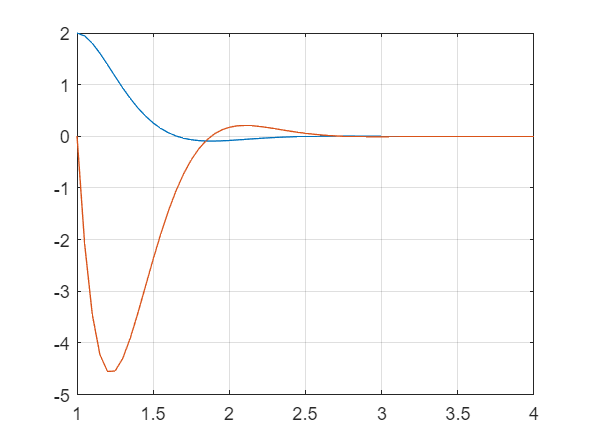

plot(t,y), grid

Vamos a resolver la siguiente ecuacion


$$\frac{d^3y}{dt}=4
$$


iniciamos poniendo la funcion

f2=@(t,y)[y(2);y(3);4]

f2 = function_handle with value:
    @(t,y)[y(2);y(3);4]


rango=1:0.01:5;
ci=[1 2 3]

ci =      1     2     3


[t,y]=ode45(f2,rango,ci)

t =     1.0000
    1.0100
    1.0200
    1.0300
    1.0400
    1.0500
    1.0600
    1.0700
    1.0800
    1.0900


y =     1.0000    2.0000    3.0000
    1.0202    2.0302    3.0400
    1.0406    2.0608    3.0800
    1.0614    2.0918    3.1200
    1.0824    2.1232    3.1600
    1.1038    2.1550    3.2000
    1.1255    2.1872    3.2400
    1.1476    2.2198    3.2800
    1.1699    2.2528    3.3200
    1.1926    2.2862    3.3600


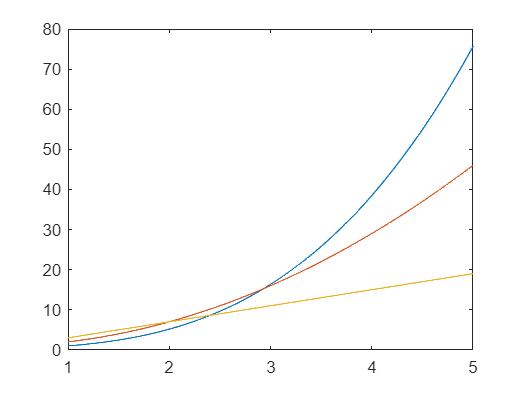

plot(t,y)